clc; clear; close all;

%% Definir los Números Cuánticos
% Define los números cuánticos principal (n), azimutal (l) y magnético (m).


% Número cuántico principal (n): 1, 2, 3, 4, 5, 6, 7
n = 4;

% Número cuántico azimutal (l): 0, 1, 2, ..., n-1
max_l = n - 1;
l = 3;

% Número cuántico magnético (m): -l, -l+1, ..., 0, ..., l-1, l
min_m = -l;
m = 0;

%% Validar los Números Cuánticos
% Verifica que l < n y que |m| ≤ l.

if l >= n || l < 0
    error('Número cuántico azimutal (l) debe cumplir 0 ≤ l < n.');
end

if abs(m) > l
    error('Número cuántico magnético (m) debe cumplir |m| ≤ l.');
end

%% Funciones Auxiliares (Armónicos esféricos)
% Define funciones para calcular armónicos esféricos y sus partes reales.

% Función para calcular la constante de normalización K_lm
function val = K_lm(l, m)
    val = sqrt((2*l + 1)/(4*pi) * factorial(l - abs(m))/factorial(l + abs(m)));
end

% Función para calcular el armónico esférico complejo Y_lm
function Y = sphericalHarmonicY(l, m, theta, phi)
    x = cos(theta);
    x_vec = x(:);
    P = legendre(l, x_vec, 'norm');
    if m >= 0
        Plm_vec = P(m+1,:).';
    else
        Plm_vec = ((-1)^m)*factorial(l + m)/factorial(l - m)*P(-m +1,:).';
    end
    Plm_mat = reshape(Plm_vec, size(theta));
    Y = K_lm(l, m)*Plm_mat.*exp(1i * m * phi);
end

% Función para calcular el armónico esférico real
function Y_real = realSH(l, m, theta, phi)
    if m > 0
        Y_pos = sphericalHarmonicY(l, m, theta, phi);
        Y_neg = sphericalHarmonicY(l, -m, theta, phi);
        Y_real = (1/sqrt(2))*(Y_neg + (-1)^m * Y_pos);
    elseif m < 0
        Y_pos = sphericalHarmonicY(l, -m, theta, phi);
        Y_neg = sphericalHarmonicY(l, m, theta, phi);
        Y_real = (1/(sqrt(2)*1i))*(Y_neg - (-1)^m * Y_pos);
    else
        Y_real = sphericalHarmonicY(l, 0, theta, phi);
    end
    Y_real = real(Y_real);
end

%% Funciones Auxiliares (Radial)
% Parte radial del átomo de hidrógeno: R_{nl}(r)
% R_{nl}(r) = N_{nl} * ( (2r/(n a0))^l ) * exp(-r/(n a0)) * L_{n-l-1}^{2l+1}(2r/(n a0))

function R = radialWavefunction(n, l, r)
    a0 = 1; % Radio de Bohr en unidades atómicas
    rho = 2*r/(n*a0);
    top = factorial(n-l-1);
    bottom = 2*n*factorial(n+l);
    prefactor = ((2/(n*a0))^3)*(top/bottom);
    N = sqrt(prefactor);
    
    % Calcular los polinomios de Laguerre generalizados
    L = generalizedLaguerre(n-l-1, 2*l+1, rho);
    
    R = N .* (rho.^l) .* exp(-rho/2) .* L;
end

%% Función para calcular los polinomios de Laguerre generalizados
function L = generalizedLaguerre(k, a, x)
    if k == 0
        L = ones(size(x));
        return;
    elseif k == 1
        L = -x + a + 1;
        return;
    end

    Lm2 = ones(size(x));           % L0^a(x)
    Lm1 = -x + a + 1;              % L1^a(x)
    for n = 1:k-1
        Ln = ((2*n + 1 + a - x) .* Lm1 - (n + a) * Lm2) / (n + 1);
        Lm2 = Lm1;
        Lm1 = Ln;
    end
    L = Lm1;
end

%% Función Auxiliar para obtener el nombre del orbital
function orbital_name = getOrbitalName(n, l, m)
    % Mapa de nombres para l
    l_names = {'s', 'p', 'd', 'f', 'g', 'h', 'i'}; % Extendiendo más allá de 'f' si es necesario
    
    % Nombre base del orbital
    orbital_name = sprintf('%d%s', n, l_names{l + 1});
    
    % Agregar subíndices para m si l > 0
    if l > 0
        % Definir m_names según el valor de l
        switch l
            case 1 % Orbitales p
                m_names = {'x', 'z', 'y'};
            case 2 % Orbitales d
                m_names = {'xy', 'yz', 'z^2', 'xz', 'x^2-y^2'};
            case 3 % Orbitales f
                m_names = {'x(x^2-3y^2)', 'xyz', 'xz^2', 'z^3', ...
                           'yz^2', 'z(x^2-y^2)', 'y(3x^2-y^2)'};
            otherwise
                % Si l > 3, genera subíndices dinámicamente
                m_values = -l:l;
                m_names = arrayfun(@(k) sprintf('m%d', k), m_values, 'UniformOutput', false);
        end
        
        % Agregar el subíndice al nombre del orbital
        index = m + l + 1; 
        orbital_name = sprintf('%s_{%s}', orbital_name, m_names{index});
    end
end

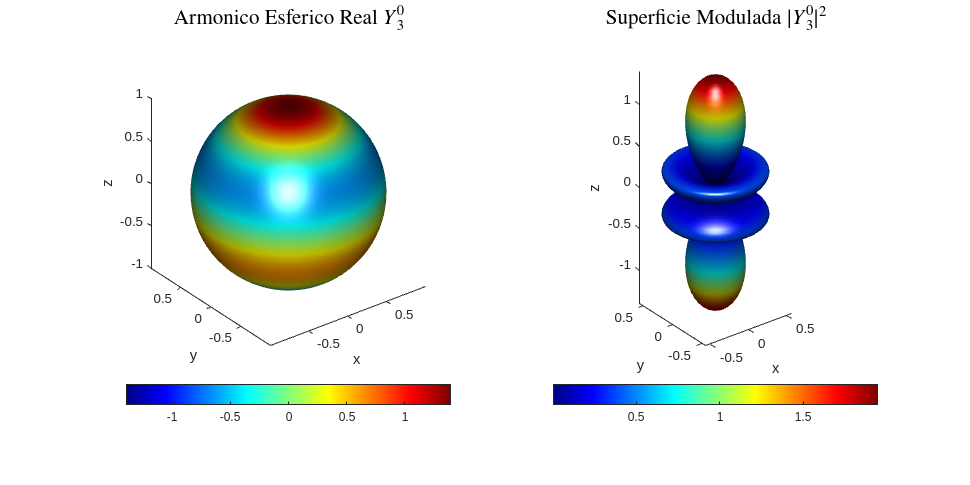

%% Visualizar los Armónicos Esféricos Reales

% Definir una malla en coordenadas esféricas para la visualización de los armónicos
theta_sph = linspace(0, pi, 100);   % Polar angle
phi_sph = linspace(0, 2*pi, 100);   % Azimuthal angle
[Theta_sph, Phi_sph] = meshgrid(theta_sph, phi_sph);

% Calcular el armónico esférico real
Y_real_sph = realSH(l, m, Theta_sph, Phi_sph);

% --- Primera Representación: Armónico Esférico Real sobre la Esfera Unitaria ---
% Convertir a coordenadas cartesianas para la visualización
X_sph1 = sin(Theta_sph) .* cos(Phi_sph);
Y_sph1 = sin(Theta_sph) .* sin(Phi_sph);
Z_sph1 = cos(Theta_sph);

% --- Segunda Representación: Superficie con Radio Modulado por |Y_real| ---
% Modular el radio utilizando el valor absoluto de Y_real
radius_mod = abs(Y_real_sph);  % Ajusta el factor de escala (0.5) según sea necesario

X_sph2 = radius_mod .* sin(Theta_sph) .* cos(Phi_sph);
Y_sph2 = radius_mod .* sin(Theta_sph) .* sin(Phi_sph);
Z_sph2 = radius_mod .* cos(Theta_sph);

% Crear una figura con dos subplots
figure('Name', 'Representación de Armonicos Esfericos Reales', ...
       'Position', [100 100 1200 600]);

% --- Subplot 1: Armónico Esférico Real sobre la Esfera Unitaria ---
ax1 = subplot(1, 2, 1);
surf(ax1, X_sph1, Y_sph1, Z_sph1, Y_real_sph, 'EdgeColor', 'none');
colormap(ax1, jet);
colorbar(ax1, 'Location', 'southoutside');
shading(ax1, 'interp');
camlight(ax1, 'headlight');
lighting(ax1, 'gouraud');
axis(ax1, 'equal');
xlabel(ax1, 'x');
ylabel(ax1, 'y');
zlabel(ax1, 'z');
title(ax1, sprintf('Armonico Esferico Real $Y_{%d}^{%d}$', l, m), 'Interpreter', 'latex', 'FontSize', 16);
grid(ax1, 'off');

% --- Subplot 2: Superficie con Radio Modulado por |Y_real|² ---
ax2 = subplot(1, 2, 2);
surf(ax2, X_sph2, Y_sph2, Z_sph2, abs(Y_real_sph).^2, 'EdgeColor', 'none');
colormap(ax2, jet);
colorbar(ax2, 'Location', 'southoutside');
shading(ax2, 'interp');
camlight(ax2, 'headlight');
lighting(ax2, 'gouraud');
axis(ax2, 'equal');
xlabel(ax2, 'x');
ylabel(ax2, 'y');
zlabel(ax2, 'z');
title(ax2, sprintf('Superficie Modulada $|Y_{%d}^{%d}|^2$', l, m), 'Interpreter', 'latex', 'FontSize', 16);
grid(ax2, 'off');

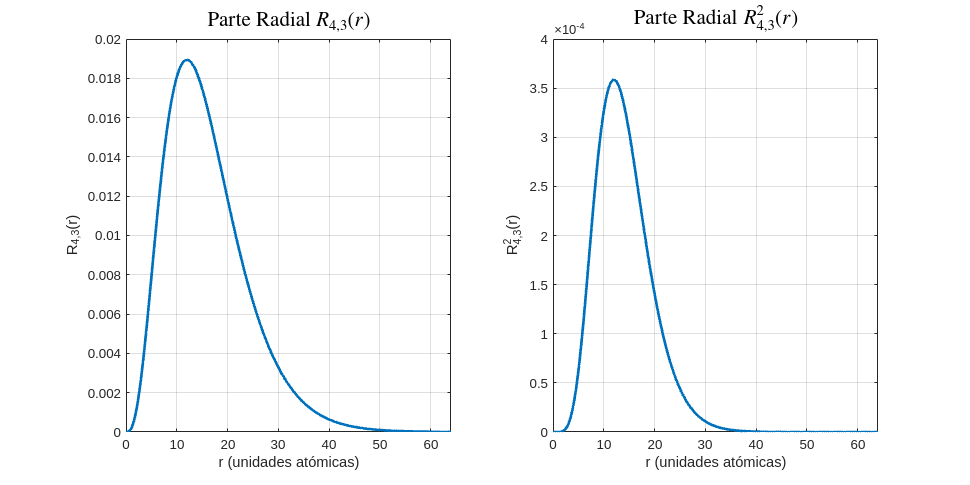

% Definir el rango radial y número de puntos
r = linspace(0, n^2 * 4, 500); % Ajusta el rango para una mejor visualización

% Calcular la función radial
R_nl_values = radialWavefunction(n, l, r);

% Crear la figura con dos subplots
figure('Name', 'Parte Radial R_{n,l}(r)', 'Position', [100 100 1200 600]);

% Subplot de la función radial original
ax1 = subplot(1,2,1);
plot(r, R_nl_values, 'LineWidth', 2);
xlabel('r (unidades atómicas)');
ylabel(sprintf('R_{%d,%d}(r)', n, l));
xlim(ax1, [0, 4 * n^2]);
title(sprintf('Parte Radial $R_{%d,%d}(r)$', n, l), 'Interpreter', 'latex', 'FontSize', 16);
grid on;

% Subplot de la función radial al cuadrado
ax2 = subplot(1,2,2);
plot(r, R_nl_values.^2, 'LineWidth', 2);
xlabel('r (unidades atómicas)');
ylabel(sprintf('R^2_{%d,%d}(r)', n, l));
xlim(ax2, [0, 4 * n^2]);
title(sprintf('Parte Radial $R^2_{%d,%d}(r)$', n, l), 'Interpreter', 'latex', 'FontSize', 16);
grid on;

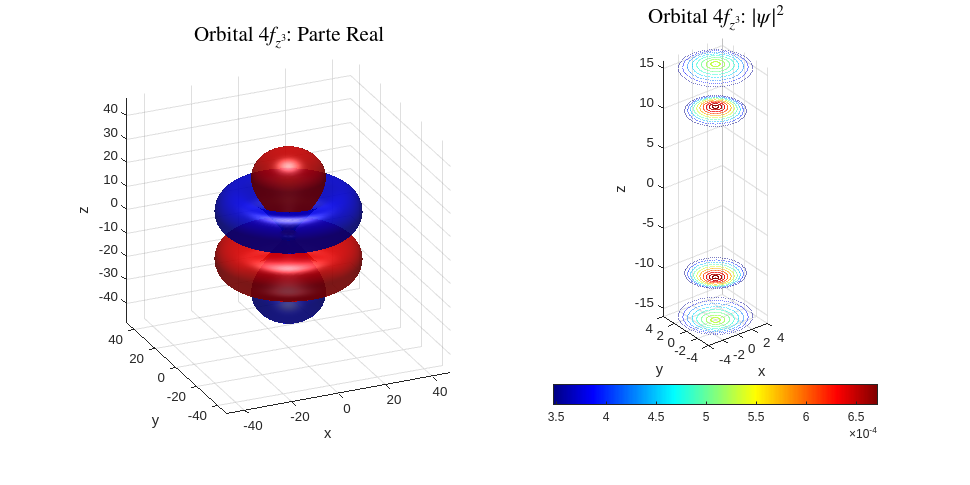

%% Calcular y Visualizar el Orbital (dos subplots: isosuperficies y scatter3 de |psi|^2)

% Definir el número de puntos y el rango máximo
N = 100; % Número de puntos por dimensión para el espacio cartesiano
rmax = n^2 * 3; % Rango radial

% Crear malla 3D en coordenadas cartesianas
x = linspace(-rmax, rmax, N);
y = linspace(-rmax, rmax, N);
z = linspace(-rmax, rmax, N);
[X, Y, Z] = meshgrid(x, y, z);

% Convertir a coordenadas esféricas
r = sqrt(X.^2 + Y.^2 + Z.^2);
theta = acos(Z ./ (r + eps)); % Añadir 'eps' para evitar división por cero
phi = atan2(Y, X);
phi(phi < 0) = phi(phi < 0) + 2*pi; % Ajustar phi a [0, 2*pi]

% Calcular la función de onda
Y_lm = realSH(l, m, theta, phi);
R_nl = radialWavefunction(n, l, r);
psi = R_nl .* Y_lm;

% Calcular la parte real y el módulo al cuadrado de la función de onda
psi_real = real(psi);
psi_abs2 = abs(psi).^2;

% Valor iso para las isosuperficies de psi_real
iso_val = 0.065 * max(abs(psi_real(:)));

% Obtener el nombre del orbital
orbital_name = getOrbitalName(n, l, m);

% Crear la figura con dos subplots
figure('Name', sprintf('Orbital: n=%d, l=%d, m=%d', n, l, m), ...
       'Position', [100 100 1200 600]);

% --- Subplot 1: Isosuperficies de psi_real (positivo y negativo) ---
ax1 = subplot(1,2,1);
hold(ax1, 'on');

% Isosuperficie positiva
p1 = patch(isosurface(X, Y, Z, psi_real, iso_val));
isonormals(X, Y, Z, psi_real, p1);
p1.FaceColor = 'red';
p1.EdgeColor = 'none';
p1.FaceAlpha = 0.7;

% Isosuperficie negativa
p2 = patch(isosurface(X, Y, Z, psi_real, -iso_val));
isonormals(X, Y, Z, psi_real, p2);
p2.FaceColor = 'blue';
p2.EdgeColor = 'none';
p2.FaceAlpha = 0.7;

hold(ax1, 'off');
camlight(ax1, 'headlight');
lighting(ax1, 'gouraud');
axis(ax1, 'equal');
xlabel(ax1, 'x');
ylabel(ax1, 'y');
zlabel(ax1, 'z');
title(ax1, sprintf('Orbital $%s$: Parte Real', orbital_name), ...
      'Interpreter', 'latex', 'FontSize', 16);
grid(ax1, 'on');
xlim(ax1, [-rmax rmax]);
ylim(ax1, [-rmax rmax]);
zlim(ax1, [-rmax rmax]);
view(ax1, [-rmax/2 rmax/2]);

% --- Subplot 2: Scatter3 de puntos coloreados por |psi|^2 ---
ax2 = subplot(1,2,2);

% Definir una malla esférica para el scatter3 plot
num_theta = 100; % Número de puntos en theta
num_phi = 100;   % Número de puntos en phi
theta_scatter = linspace(0, pi, num_theta);
phi_scatter = linspace(0, 2*pi, num_phi);
[Theta_scatter, Phi_scatter] = meshgrid(theta_scatter, phi_scatter);

% Calcular la función de onda en la malla esférica
% Elegimos un rango radial adecuado para la visualización
% Por ejemplo, podemos tomar un conjunto de radios donde R_nl es significativo
% Aquí tomamos varios radios y acumulamos los puntos

% Número de radios a muestrear
num_r = 10;
r_values = linspace(0, rmax, num_r);

% Inicializar vectores para los puntos
X_points = [];
Y_points = [];
Z_points = [];
C_points = [];

for i = 1:num_r
    r_current = r_values(i);
    % Evitar r=0 para evitar NaNs en theta
    if r_current == 0
        continue;
    end
    % Calcular theta y phi para la malla esférica
    Y_lm_scatter = realSH(l, m, Theta_scatter, Phi_scatter);
    R_nl_scatter = radialWavefunction(n, l, r_current);
    psi_scatter = R_nl_scatter .* Y_lm_scatter;
    psi_abs2_scatter = abs(psi_scatter).^2;
    
    % Convertir a coordenadas cartesianas
    X_s = r_current .* sin(Theta_scatter) .* cos(Phi_scatter);
    Y_s = r_current .* sin(Theta_scatter) .* sin(Phi_scatter);
    Z_s = r_current .* cos(Theta_scatter);
    
    % Acumular los puntos y sus colores
    X_points = [X_points; X_s(:)];
    Y_points = [Y_points; Y_s(:)];
    Z_points = [Z_points; Z_s(:)];
    C_points = [C_points; psi_abs2_scatter(:)];
end

% Opcional: Filtrar puntos con |psi|^2 por encima de un umbral para reducir la cantidad de puntos
threshold = 0.5 * max(C_points); % Ajusta el umbral según sea necesario
idx = C_points >= threshold;
X_filtered = X_points(idx);
Y_filtered = Y_points(idx);
Z_filtered = Z_points(idx);
C_filtered = C_points(idx);

% Crear el scatter3 plot
scatter3(ax2, X_filtered, Y_filtered, Z_filtered, 1, C_filtered, 'filled', 'MarkerFaceAlpha', 0.5);
colormap(ax2, jet);
colorbar(ax2, 'Location', 'southoutside');
xlabel(ax2, 'x');
ylabel(ax2, 'y');
zlabel(ax2, 'z');
title(ax2, sprintf('Orbital $%s$: $|\\psi|^2$', orbital_name), ...
      'Interpreter', 'latex', 'FontSize', 16);
axis(ax2, 'equal');
xlim(ax1, [-rmax rmax]);
ylim(ax1, [-rmax rmax]);
zlim(ax1, [-rmax rmax]);
view(ax1, [-rmax/2 rmax/2]);
grid(ax2, 'on');